# Cinemática Directa e Inversa de un Robot

# Cálculo en objetos Rigid-Body y Simulación en Multi-Body

Dificultad: Alta (Teoría)

## Cinemática directa

- Es el movimiento del robot cuando se modifican las posiciones de las articulaciónes.

- La posición cartesiana del TCP del robot ante este cambio tiene que ser calculada por el producto de las matrices homogéneas de los ejes de las articulaciones. 


$$^0T_6(R_{z_1},\ldots,R_{z_6})= ^0T_1(R_{z_1})*^1T_2(R_{z_2})*\ldots*^5T_6(R_{z_6})$$


- La simulación se hará en Multi-Body y el cálculo de las posiciones cartesianas inicial y final del TCP en Rigid-Body que lo puede calcular

###  Simulación con Multi-Body

deg= pi/180;

Estacion= 'T25S2_irb120';
% Variables
baseRobot= [[0,0,0],[0,0,0]*deg];
% Posición inicial de la que parte el robot
q0_= [0,0,0,0,90,0]*deg;
% Rastreador en el origen (ahora no se usa)
pose_= rand(3,3)*1e-3;

open_system(Estacion);

% Movimiento en joint de inicial a final
q0= q0_;
qend= [0,20,30,-50,90,0]*deg;

nPts= 1e2;
t= linspace(0,10,nPts)';
Q= zeros(nPts,6);
for i= 1:6
   Q(:,i)= linspace(q0(i),qend(i),nPts)';
end

sim(Estacion,t, [], [t, Q]);


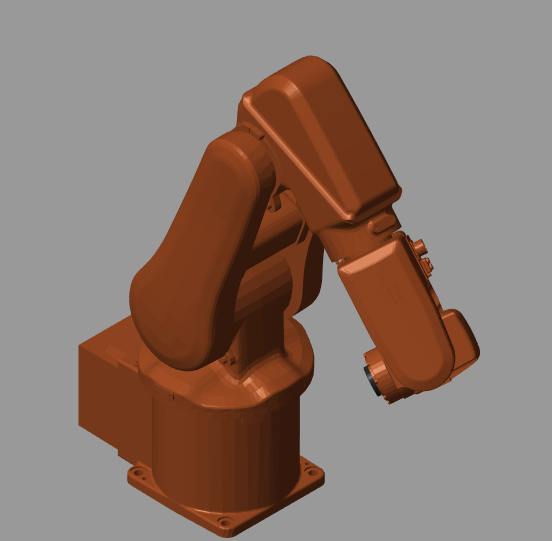

### Cálculo de posiciones cartesianas con Rigid-Body

- Importamos el robot Rigid-Body del fichero Simulink Multi-Body

robot= importrobot(Estacion);
robot.showdetails
robot.DataFormat= 'row';

- Posición articular inicial y la correspondiente posición cartesiana del TCP.

figure
q= q0;
show(robot,q);
axis([-0.2, 0.5, -0.5, 0.5, 0, 0.8])
% Obtener la matriz homogénea del TCP
H0= getTransform(robot, q, 'Body8')

- Posición articular final y su correspondiente posición cartesiana del TCP.

q= qend;
show(robot,q);
axis([-0.2, 0.5, -0.5, 0.5, 0, 0.8])
% Obtener la matriz homogénea del TCP
Hend= getTransform(robot, q, 'Body8')

## Cinemática inversa

- El robot se encuentra en una posición articular dada, que corresponde a una posción cartesiana (matriz homogénea) de su TCP.

deg= pi/180;

Estacion= 'T25S2_irb120';
% Variables
baseRobot= [[0,0,0],[0,0,0]*deg];

--------------------
Robot: (8 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        Body1        Joint1         fixed             Base(0)   Body2(2)  
   2        Body2        Joint2      revolute            Body1(1)   Body3(3)  
   3        Body3        Joint3      revolute            Body2(2)   Body4(4)  
   4        Body4        Joint4      revolute            Body3(3)   Body5(5)  
   5        Body5        Joint5      revolute            Body4(4)   Body6(6)  
   6        Body6        Joint6      revolute            Body5(5)   Body7(7)  
   7        Body7        Joint7      revolute            Body6(6)   Body8(8)  
   8        Body8        Joint8         fixed            Body7(7)   
--------------------


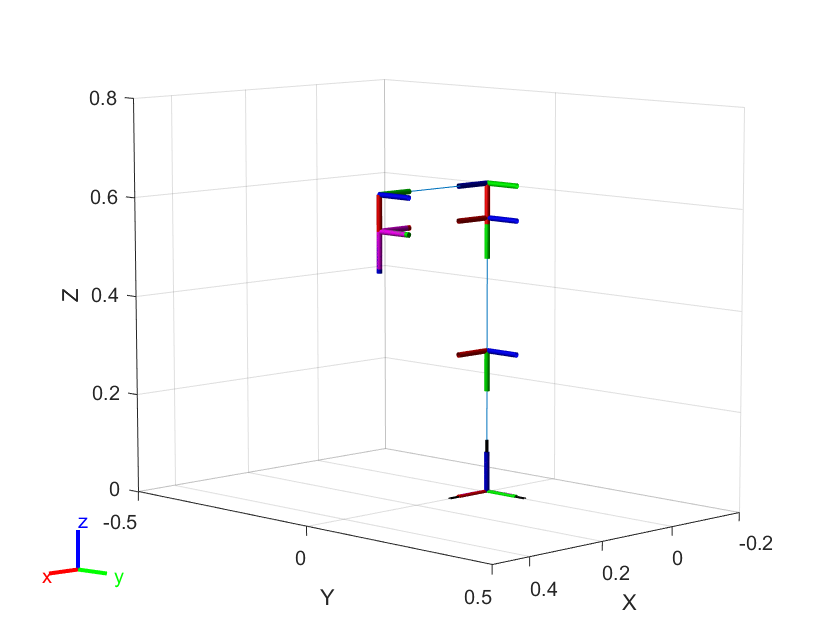

% Posición inicial 
q0_= [0,0,0,0,0,0]*deg;

open_system(Estacion);

% Posición inicial del TCP (matriz homogénea)
q0= q0_;


H0= getTransform(robot, q0, 'Body8');

H0 =    -1.0000   -0.0000   -0.0000    0.3020
   -0.0000    1.0000    0.0000   -0.0000
    0.0000    0.0000   -1.0000    0.5580
         0         0         0    1.0000


- Se desea que el TCP vaya a otra posición cartesiana, $[x,y,z,R_z,R_y,R_x]$.

- **Punto accesible**: El TCP tiene que poder ir a ese punto en posición y rotación. 

- El TCP del $6^o$ eje apunta hacia abajo, el punto también debe hacerlo.

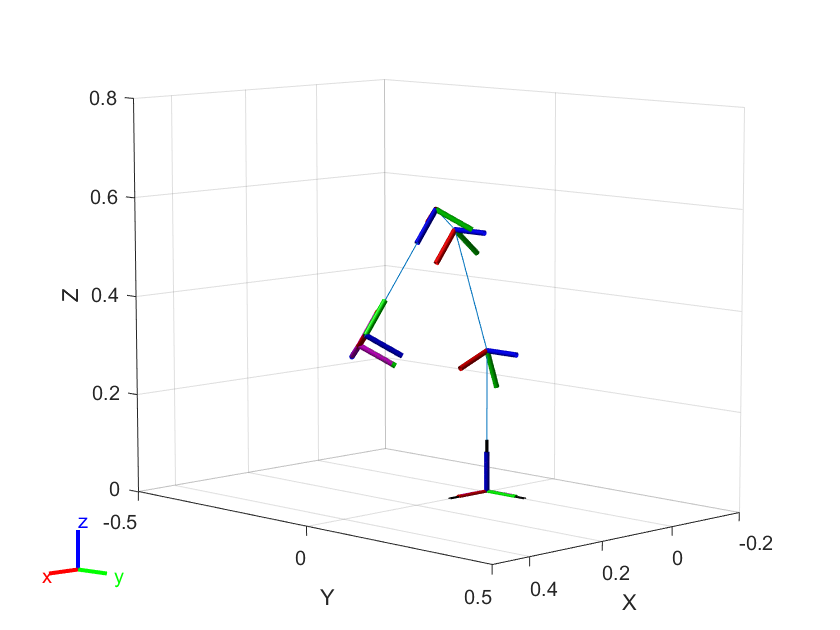

% Posición final deseada
% Ver los ángulos 

pose= [[200,-200,100]*1e-3, [0,0,180]*deg];

% Paso de pose a matriz homogénea
Hend= Prod(pose);

Hend =    -0.6428   -0.5868   -0.4924    0.3046
    0.0000    0.6428   -0.7660   -0.0552
    0.7660   -0.4924   -0.4132    0.3276
         0         0         0    1.0000


- Se deben encontrar la trayectoria cartesiana entre ambos puntos (interpolación en objeto $se3$).

nPts= 10;
Hinter= interp(se3(H0),se3(Hend),nPts);

- Se debe obtener las posiciones articulares correspondientes a dichas trayectoria cartesiana.

- Esta acción se realiza con el objeto Rigid-Body.

- Es un problema inverso que requiere una optimización local por cada una de las posición deseadas.

- Los pesos $w$ es la importancia de $[R_z,R_y,R_x,x,y,z]$ en la optimización local.

% Motor de la optimización local
ik = robotics.InverseKinematics('RigidBodyTree', robot);
% Pesos de la optimización local
w= [1,1,1,1,1,1];
Q= zeros(nPts,6);
q= q0;
for i= 1:nPts
   H= tform(Hinter(i));
   % Se parte de q y se quiere otra q en la que el TCP esté en H
   q= ik('Body8', H, w, q);
   % coordenas articulares obtenidas para ese punto H
   Q(i,:)= q';
   % Rastreador en el [x,y,z] del punto
   pose_(i,:)= H(1:3, 4)';
end

% Simulación en Simulink
t= linspace(0,2,nPts)';
sim(Estacion, t, [], [t,Q]);

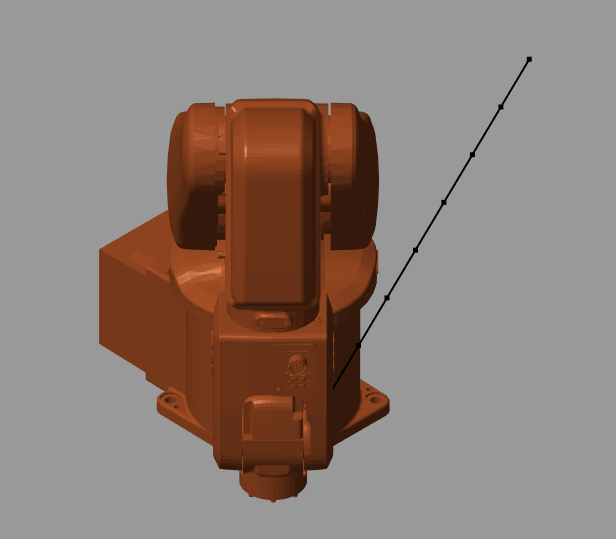

## Rastreador

Se producen dos procesos paralelos:

- Movimiento de las articulaciones en la matriz $Q$, Multi-Body.

- Interpolación de los puntos $[x,y,z]$ por los que pasa el TCP ($pose\_$), obtenidos con Rigid-Body.

- Si ambos están coordinados es que la simulación está bien hecha.

## Objeto $Cin()$

- El objeto $Cin()$ creado en esta librería se ocupa de move el robot usando herramientas de Multi-Bosy y Rigid-Body.

- Calcula los movimientos en cinemática directa e inversa.

- Ver siguientes ficheros.

##  Funciones para la cinemática inversa

% inverseKinematics
% analyticalInverseKinematics 
% generalizedInverseKinematics
% generateIKFunction
 

## Avanzadas con restricciones

%     manipulatorRRT                 - Plan motion for rigid body tree using bidirecitonal RRT
%     manipulatorCHOMP               - CHOMP for rigid body tree
%     manipulatorStateSpace          - State space of a rigid body tree
%     manipulatorCollisionBodyValidator - Validate a state of a rigid body tree against a cell-array of convex collision bodies
%     workspaceGoalRegion            - Define a workspace region of end-effector goal poses
%     chompCollisionOptions          - Collision options for CHOMP trajectories
%     chompSmoothnessOptions         - Smoothness options for CHOMP trajectories
%     chompSolverOptions             - Solver options for CHOMP
 